# **Bayesian Optimisation Example 2.0**

## **Choice of Hyperparameter**

**SECTION 1.0**

Goal: *maximise the function f(x) = x.*sin( x );  in the interval [0, 10]*

clear
close all
x = linspace( 0, 10, 501 ).';
f = x.*sin( x );


Extract 7 points for training an initial surrogate model & plot the results:

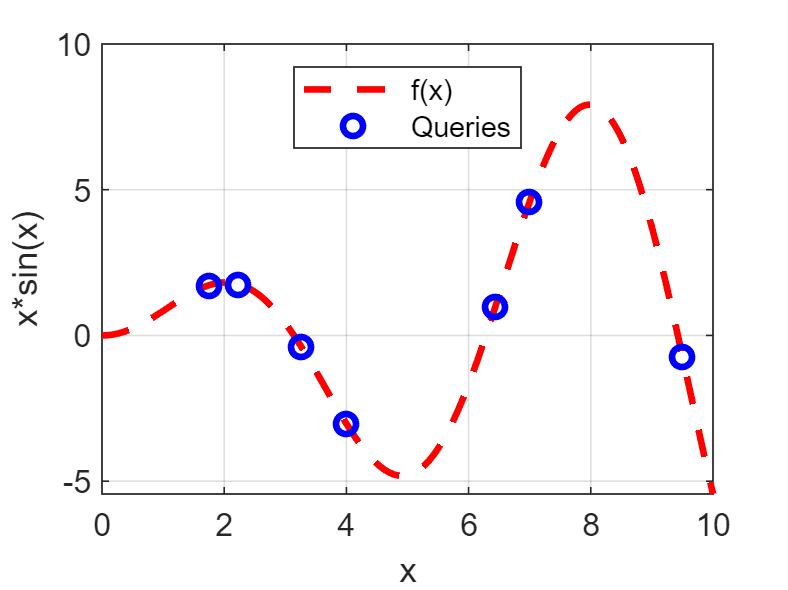

X = [ 9.5, 2.24, 4, 1.76, 3.26, 6.44, 7.0 ].';
Y = X .* sin( X );
plot( x, f, 'r--', X, Y, 'bo', 'LineWidth', 2 );
grid on
xlabel( "x" );
ylabel( "x*sin(x)" );
legend( "f(x)", "Queries", "Location", "north")

**SECTION 2.0**

Create the Bayesian Optimisation object. Assume a Gaussian Process Regression model and the EI acquisition function with Beta = 0.02

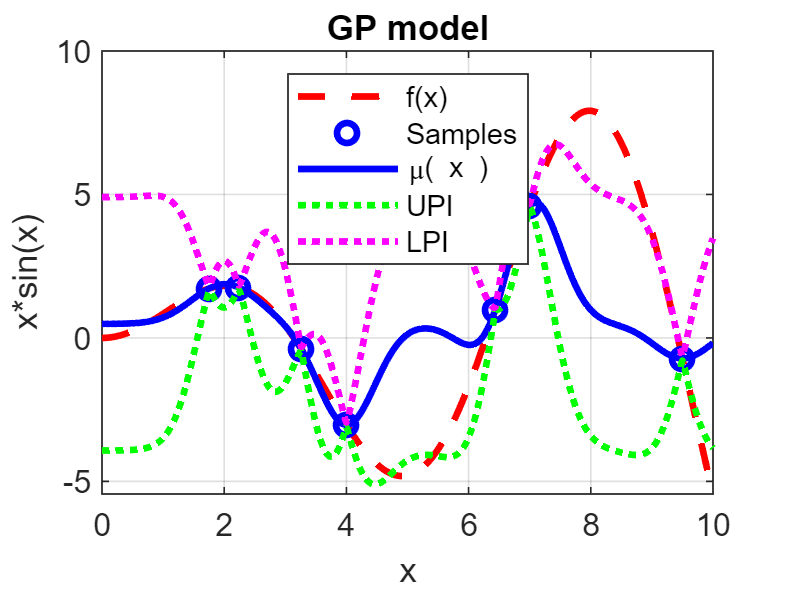

B = bayesOpt( "gpr", "ei");
B = B.setHyperPar( 0.02 );
B = B.setTrainingData( X, Y );
[ Yp, ~, Yint] = B.predict( x, 0.05 );
close all
figure;
plot(x, f, 'r--', B.X, B.Y, 'bo', x, Yp, 'b-', 'LineWidth', 2);
grid on
legend( "f(x)", "Samples", "\mu( x )", 'Location', 'north');
xlabel( "x" );
ylabel( "x*sin(x)" );
title( "GP model");
hold on;
plot(  x, Yint( :,1 ), 'g:', x, Yint( :,2 ), 'm:', 'LineWidth', 2);
legend( "f(x)", "Samples", "\mu( x )", "UPI", "LPI", 'Location', 'north');

**SECTION 3.0**

Minimise -EI(x)

B = B.acqFcnMaxTemplate( "lb", 0, "ub", 10 );
U = B.AcqObj;
figure;
A = U.evalFcn( x, U.Beta );
plot( x, A, 'g-', 'LineWidth', 2); grid on
xlabel( "x" )
ylabel( "AcqFcn" )
Tstr = sprintf( "Expected Improvement Fcn, \\beta = %4.3f", B.HyperPar );
title( Tstr ); 
hold on, plot( B.Xnext, B.AcqObj.evalFcn( B.Xnext ), "bs", "MarkerSize", 12, "MarkerFaceColor", "blue" );
grid on
hold off

**SECTION 4.0**

Query f(x) at the suggested value and update the GP model

figure;
Xnew = B.Xnext;
Ynew = Xnew * sin( Xnew );
B = B.addNewQuery( Xnew, Ynew );
[ Yp, ~, Yint ] = B.predict( x );
plot(x, f, 'r--', B.X, B.Y, 'bo', x, Yp, 'b-', x, Yint( :,1 ), 'm:',...
    x, Yint( :,2 ), 'g:',  'LineWidth', 2);
hold on
plot( Xnew, Ynew, 'bs', 'MarkerSize', 10, 'MarkerFaceColor', 'blue');
grid on
legend( "f(x)", "Samples", "\mu( x )", "LPI", "UPI", "f(Xnew)", 'Location', 'north');
xlabel( "x" );
ylabel( "x*sin(x)" );
title( "GP model");

**SECTION 5.0**

Iteration 2. Now re-optimise the acquisition function and add the new query to the training data and retrain the surrogate model.

B = B.acqFcnMaxTemplate();
figure;
Xnew = B.Xnext;
subplot(2,1,1), plot( x, B.AcqObj.evalFcn( x ), 'g-', Xnew, B.AcqObj.evalFcn( Xnew ), 'bs', 'MarkerSize', 12,'LineWidth', 2, 'MarkerFaceColor','blue');
grid on
xlabel( "x" )
ylabel( "AcqFcn" )
Tstr = sprintf( "Expected Improvement Fcn, \\beta = %4.3f", B.HyperPar );
title( Tstr ); 
subplot(2,1,2)
Xnew = B.Xnext;
Ynew = Xnew * sin( Xnew );
B = B.addNewQuery( Xnew, Ynew );
plot(x, f, 'r--', B.X, B.Y, 'bo', x, Yp, 'b-', x, Yint( :,1 ), 'm:',...
    x, Yint( :,2 ), 'g:',  'LineWidth', 2);
hold on
plot( Xnew, Ynew, 'bs', 'MarkerSize', 10, 'MarkerFaceColor', 'blue');
grid on
legend( "f(x)", "Samples", "\mu( x )", "LPI", "UPI", "f(Xnew)", 'Location', 'north');
xlabel( "x" );
ylabel( "x*sin(x)" );
title( "GP model");

**SECTION 6.0**

Now set the hyperparameter to 0.2

Bbad = bayesOpt( "gpr", "ei");
Bbad = Bbad.setHyperPar( 0.2 );
Bbad = Bbad.setTrainingData( X, Y );

**SECTION 7.0**

Repeat the BO process

Bbad = Bbad.acqFcnMaxTemplate( "lb", 0, "ub", 10 );

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       2   -8.036825e-10    0.000e+00    2.577e-07

Initial point is a local minimum that satisfies the constraints.

Optimization completed because at the initial point, the objective function is non-decreasing 
in feasible directions to within the value of the optimality tolerance, and 
constraints are satisfied to within the value of the constraint tolerance.

<

Xnew = Bbad.Xnext;
subplot(2,1,1), plot( x, Bbad.AcqObj.evalFcn( x ), 'g-', Xnew, Bbad.AcqObj.evalFcn( Xnew ), 'bs', 'MarkerSize', 12,'LineWidth', 2, 'MarkerFaceColor','blue');
grid on
xlabel( "x" )
ylabel( "AcqFcn" )
Tstr = sprintf( "Expected Improvement Fcn, \\beta = %4.3f", Bbad.HyperPar );
title( Tstr ); 
subplot(2,1,2)
Xnew = Bbad.Xnext;
Ynew = Xnew * sin( Xnew );
Bbad = Bbad.addNewQuery( Xnew, Ynew );
plot(x, f, 'r--', Bbad.X, Bbad.Y, 'bo', x, Yp, 'b-', x, Yint( :,1 ), 'm:',...
    x, Yint( :,2 ), 'g:',  'LineWidth', 2);
hold on
plot( Xnew, Ynew, 'bs', 'MarkerSize', 10, 'MarkerFaceColor', 'blue');
grid on
legend( "f(x)", "Samples", "\mu( x )", "LPI", "UPI", "f(Xnew)", 'Location', 'north');
xlabel( "x" );
ylabel( "x*sin(x)" );
title( "GP model");